for j = 1%[1,2,3,4,5]%,6,7,8,9,10]
    splitfolder=strcat('split',num2str(j));
    M=importdata("C:\Users\shukl\Documents\GitHub\Fashion_Mnist\split5\Fashion_mnist_train_set.csv",",",1);
    per =20%[20,10,5,0];
    for percent = per
        cd C:\Users\shukl\Documents\GitHub\Fashion_Mnist\
        mkdir (splitfolder)
        cd (splitfolder)
        folder=strcat('per',num2str(percent));
        %         mkdir (folder)
        cd (folder)
        outlier=20;
        iter=1;
%         epsilon=0.005
        my_file = strcat('Fashion_mnist_misclass_per_',num2str(percent),'.csv');
        File=readmatrix(my_file,"NumHeaderLines",1);

        class0=File(File(:,1)==0,2:785);
        T_class0=class0.';
        T_class0_org=class0.';
        ind_zero=find(File(:,1)==0);
        F_class0=[ind_zero class0];


        class1=File(File(:,1)==1,2:785);
        T_class1=class1.';
        T_class1_org=class1.';
        ind_one=find(File(:,1)==1);
        F_class1=[ind_one class1];


        class2=File(File(:,1)==2,2:785);
        T_class2=class2.';
        T_class2_org=class2.';
        ind_two=find(File(:,1)==2);
        F_class2=[ind_two class2];


        class3=File(File(:,1)==3,2:785);
        T_class3=class3.';
        T_class3_org=class3.';
        ind_three=find(File(:,1)==3);
        F_class3=[ind_three class3];



        folder_l1=strcat('ACE_percent',num2str(outlier),'_l1pca_per',num2str(percent));
        mkdir (folder_l1)

        numclass0=length(T_class0);
        T_class0_temp=T_class0;
         i=1;
        for (l=1:iter)
            cd C:\Users\shukl\Documents\GitHub\Fashion_Mnist\

            Dist_mat_class0=[];
            TF_class0=[];


            BF_class0=l1pca_BF(T_class0,i,1,100,100,'');
            for k = 1 : numclass0
                A=T_class0_org(:,k);
                Dist_mat_class0(k)=norm(A-[BF_class0*BF_class0.'*A]);
                k;

            end
            Dist_mat_class0;
            min_val=min(Dist_mat_class0,[],"all");
            max_val=max(Dist_mat_class0,[],"all");
            Dist_mat_class0= Dist_mat_class0 -min_val;%]/[max_val-min_val]
            Dist_mat_class0=Dist_mat_class0 /(max_val-min_val);

        end

        perclass0=round(outlier*numclass0/100);
        [~,ind_class0]=maxk(Dist_mat_class0,perclass0);
        
        T_class0_discard=T_class0_temp(:,ind_class0).'
        T_class0_temp(:,ind_class0)=[];

        class0_row_del=F_class0(ind_class0,:);

        Final_class0=T_class0_temp';
        c0=0*ones(size(Final_class0,1),1);
        Final_class0=[c0 Final_class0];

        numclass1=length(T_class1);
        T_class1_temp=T_class1;
         i=1;
        for (l=1:iter)
            cd C:\Users\shukl\Documents\GitHub\Fashion_Mnist\

            Dist_mat_class1=[];
            TF_class1=[];


            BF_class1=l1pca_BF(T_class1,i,1,100,100,'');
            for k = 1 : numclass1
                A=T_class1_org(:,k);
                Dist_mat_class1(k)=norm(A-[BF_class1*BF_class1.'*A]);
                k;

            end
            Dist_mat_class1;
            min_val=min(Dist_mat_class1,[],"all");
            max_val=max(Dist_mat_class1,[],"all");
            Dist_mat_class1= Dist_mat_class1 -min_val;%]/[max_val-min_val]
            Dist_mat_class1=Dist_mat_class1 /(max_val-min_val);

        end


        perclass1=round(outlier*numclass1/100);
        [~,ind_class1]=maxk(Dist_mat_class1,perclass1);
        T_class1_discard=T_class1_temp(:,ind_class1).'

        T_class1_temp(:,ind_class1)=[];


        class1_row_del=F_class1(ind_class1,:);

        Final_class1=T_class1_temp';
        c1=ones(size(Final_class1,1),1);
        Final_class1=[c1 Final_class1];

               numclass2=length(T_class2);
        T_class2_temp=T_class2;
         i=1;
        for (l=1:iter)
            cd C:\Users\shukl\Documents\GitHub\Fashion_Mnist\

            Dist_mat_class2=[];
            TF_class2=[];


            BF_class2=l1pca_BF(T_class2,i,1,100,100,'');
            for k = 1 : numclass2
                A=T_class2_org(:,k);
                Dist_mat_class2(k)=norm(A-[BF_class2*BF_class2.'*A]);
                k;

            end
            Dist_mat_class2;
            min_val=min(Dist_mat_class2,[],"all");
            max_val=max(Dist_mat_class2,[],"all");
            Dist_mat_class2= Dist_mat_class2 -min_val;%]/[max_val-min_val]
            Dist_mat_class2=Dist_mat_class2 /(max_val-min_val);

        end

        perclass2=round(outlier*numclass2/100);
        [~,ind_class2]=maxk(Dist_mat_class2,perclass2);
        
        T_class2_discard=T_class2_temp(:,ind_class2).'

        T_class2_temp(:,ind_class2)=[];

        class2_row_del=F_class2(ind_class2,:);

        Final_class2=T_class2_temp';
        c2=2*ones(size(Final_class2,1),1);
        Final_class2=[c2 Final_class2];

                numclass3=length(T_class3);
        T_class3_temp=T_class3;
         i=1;
        for (l=1:iter)
            cd C:\Users\shukl\Documents\GitHub\Fashion_Mnist\

            Dist_mat_class3=[];
            TF_class3=[];


            BF_class3=l1pca_BF(T_class3,i,1,100,100,'');
            for k = 1 : numclass3
                A=T_class3_org(:,k);
                Dist_mat_class3(k)=norm(A-[BF_class3*BF_class3.'*A]);
                k;

            end
            Dist_mat_class3;
            min_val=min(Dist_mat_class3,[],"all");
            max_val=max(Dist_mat_class3,[],"all");
            Dist_mat_class3= Dist_mat_class3 -min_val;%]/[max_val-min_val]
            Dist_mat_class3=Dist_mat_class3 /(max_val-min_val);

        end

        perclass3=round(outlier*numclass3/100);
        [~,ind_class3]=maxk(Dist_mat_class3,perclass3);
        
        T_class3_discard=T_class3_temp(:,ind_class3).'

        T_class3_temp(:,ind_class3)=[];

        class3_row_del=F_class3(ind_class3,:);

        Final_class3=T_class3_temp';
        c3=3*ones(size(Final_class3,1),1);
        Final_class3=[c3 Final_class3];


        cd C:\Users\shukl\Documents\GitHub\Fashion_Mnist\
        cd (splitfolder)
        cd (folder)

        cd (folder_l1)

%         L1pca_file=(horzcat(Final_class0.',Final_class1.',Final_class2.',Final_class3.')).';
% 
%         L1pca_file = array2table(L1pca_file);
%         L1pca_file.Properties.VariableNames(1:785)=  M.colheaders;
%         filel1pca=strcat('Fashion_mnist_misclass_per',num2str(percent),'_ACE_l1pca_',num2str(i),'.csv');
%         writetable(L1pca_file,filel1pca);
    end
end

per = 20

T_class0_discard =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     3     0    37   151   126   126   126   110    55    77   114    39     0     0    98    62    56    51    56    61    67
     0     0     0   106    33     0     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0   204    96     0     8     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2
     0     0     0     7   133   108    98   113   143   130   100   108   112   115    95    98   100   122   149   133   121   106   110   140   150    33     0     0     0     0     0    40   255   255   254   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
     0     0     0     0     0     0     0     0     0     0     0     0     0

T_class1_discard =      0     0     0     0     0     0    35   122    54     0     0     0     0     0     0     0     0     0     0    69    61     0     0     0     0     1     0     0     0     0     0     0    87   251   231   232   253   245   225   220   186   196   192   200   218   223   238   226   233   232
     0     1     0     0   153   229    84     0     0     2     3     2     2     2     3     2     0     0     0     0   205   145     0     0     2     0     0     0     0     0     0   236   253   241   255   103     0     0     0     0     0     0     0     0     0     0    72   255   248   255
     0     0     0     0     0     0    29    44    36    44    39    41    38    47    49    49    48    51    57    67   100    25     0     0     0     0     0     0     0     0     0     0     0     0   219   244   231   253   253   253   253   253   253   253   254   254   253   236   251   147
     0     0     0    64   115    73    77    74    71    52    54    54    55

T_class2_discard =      1     2     0     0     0     0     0     7   106   223   180   115    86    80    77    88    90   131   212   188   130    92    12     0     0     2     1     0     0     0     0     0     0    98   197   232   226   206   188   189   205   215   212   212   195   174   187   215   225   234
     0     0     0     0     1     0     0     0    34   103     0     0     0     0     0     0     0    49    87     0     0     0     0     4     0     0     0     0     0     0     1     3     0     4   166   246   234   250   245   169   150   136   149   162   203   255   246   255   189    81
     0     0     0     0     0     3     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     3     3     0     0     0     0     0     0     0     1     1     0     0     0     0   105   224   139    26     0     0     2    74   176   231    60     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     1

T_class3_discard =      0     0     0    12    65   205   101     0     0     1     0     0     0     0     1     0     0     8     0     0     0   198    59     0     0     0     0     0     0     0     0   255   236   221   231   112     0     0     0     0     0     0     0     0     0     0     0    16   254   232
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0    14     0     0     0     0     0     0     0     0     0     0     0     3     0    79    33
     0     0     0     0     1     1     8     0     0     0     4    30    52    71    68    70    68    72    60     0     0     0     2     1     0     0     0     0     0     0     0     1     1     0     0     0    96   254   233   241   246   255   255   255   247   249   241   255   163     4
     0     0     0     0     0     0     0     0     0     0     0     0     0

   %T_class1_discard=T_class1_temp(:,ind_class1).' 
%0 T-shirt/top 1 Trouser 2 Pullover 3 Dress
% length(T_class3_discard)
% for i =1 : 931
% i
% imagesc(reshape(T_class3_discard(i,:),28,28)')
% 
% end




for i =1 : 931
    folder_name='T_class3';
    img_i = reshape(T_class3_discard(i,:).', 28, 28, []);
    for j=1:size(img_i, 3)
        filename = fullfile([num2str(i) '.jpg']);
        imwrite(img_i(:,:,j), filename);
    end
end

colormap='gray'

colormap = 'gray'

M=Final_class3(:,2:785)

M =      0     0     0     0     0     0     0     0     0     0     0     0    46     0    21    68     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    25   187   189     0   119   173   239   112     0   189   125     0     0     0
     0     0     0     0     0     0     0     0     0    38   155     0     0     0     0     0     0   108    94     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    40   187   162   134    13     0     0    38   151   173   200    94     0     0
     0     0     0     0     0     0     0     0     0     0     0    25   111   107    12   171   141     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   105    67   146   121   234    67     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0    30   129   172   

colormap='gray'

colormap = 'gray'

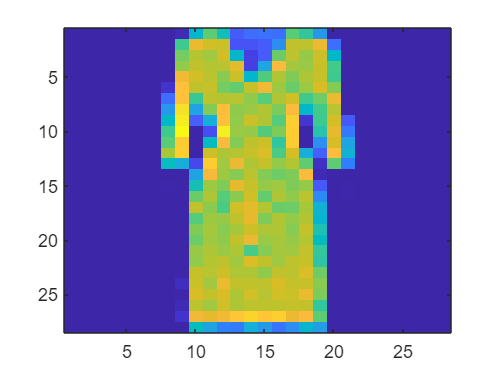

imagesc(reshape(M(399,:),28,28)')